
syms RS RL C1 L1 w

ZS = RS;
YL = 1/RL + 1i*w*C1 + 1/(1i*w*L1); % use 1i instead of j
ZL = 1/YL;
V0_VIN = ZL / (ZS + ZL); % Voltage transfer function

RS = 100; RL = 100;
C1 = 0.5e-6; L1 = 20e-3;

f0 = 1 / (2 * pi * sqrt(L1 * C1));
disp('Resonant Frequency of circuit:');

Resonant Frequency of circuit:


disp(double(f0));

   1.5915e+03



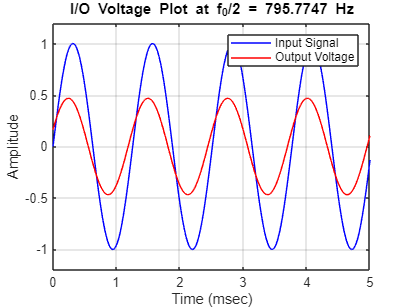


f1 = f0 / 2;
T = 1 / f1;
w = 2 * pi * f1;
t = linspace(0, 4*T, 1000);

VIN = sin(2 * pi * f1 * t);

V0_VIN = double(subs(V0_VIN));

V0_mag = abs(V0_VIN);
V0_phase_deg = angle(V0_VIN) * 180 / pi;

v0 = V0_mag * sin(2 * pi * f1 * t + V0_phase_deg * pi / 180);

ms = 1000; % msec/sec
figure;
plot(t*ms, VIN, 'b', t*ms, v0, 'r'); grid on;
xlabel('Time (msec)');
ylabel('Amplitude');
title(['I/O Voltage Plot at f_0/2 = ', num2str(f1), ' Hz']);
legend('Input Signal', 'Output Voltage');
tend = floor(ms * t(end));
axis([0 tend -1.2 1.2]);